
clear;

project_dir = dir('./expe_log')

project_dir = フィールドをもつ 18×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


names = {project_dir(4:end).name};
folders = {project_dir(4:end).folder};

for i = 1:length(names)
    sample_dir = dir(append(folders{i}, '\', names{i}));
    data{i,1} = readcell(append(sample_dir(3).folder, '\', sample_dir(3).name), Delimiter='&');
    data{i,2} = readcell(append(sample_dir(4).folder, '\', sample_dir(4).name), Delimiter='&');
    data{i,3} = readcell(append(sample_dir(5).folder, '\', sample_dir(5).name), Delimiter='&');
end

N = length(names);



mileage = zeros(N, 8);
segway_mileage = zeros(N, 3);
a1_mileage = zeros(N, 3);

segway_interval = zeros(N, 20, 3);
a1_interval = zeros(N, 20, 3);

for idx = 1:N
    for k = 1:3
        a = data{idx,k};

        segway_dt = [];
        segway_fv = [];

        a1_dt = [];
        a1_fv = [];

        ot = a{2,3};

        bst = 0;
        bat = 0;
        if strcmp(a{2,1}, 'segway')
            bst = a{2,3};
        elseif strcmp(a{2,1}, 'a1')
            bat = a{2,3};
        end

        segway_interval_a = [];
        a1_interval_a = [];

        for i = 2:height(a)
            if strcmp(a{i,1}, 'segway')
                segway_dt(end+1) = a{i,3} - ot;
                ot = a{i,3};
                segway_fv(end+1) = a{i,5};
            elseif strcmp(a{i,1}, 'a1')
                a1_dt(end+1) = a{i,3} - ot;
                ot = a{i,3};
                a1_fv(end+1) = a{i,5};
            end
            if strcmp(a{i,1}, 'segway to a1')
               segway_interval_a(end+1) = ot - bst;
               bat = a{i+1,3};
            elseif strcmp(a{i,1}, 'a1 to segway')
                a1_interval_a(end+1) = ot - bat;
                bst = a{i+1,3};
            end
        end

        if strcmp(a{end,1}, 'segway')
            segway_interval_a(end+1) = ot - bst;
        elseif strcmp(a{end,1}, 'a1')
            a1_interval_a(end+1) = ot - bat;
        end

        segway_interval(idx, 1, k) = length(segway_interval_a);
        segway_interval(idx, 2:length(segway_interval_a)+1, k) = segway_interval_a;
        a1_interval(idx, 1, k) = length(a1_interval_a);
        a1_interval(idx, 2:length(a1_interval_a)+1, k) = a1_interval_a;

        mileage(idx, 3*(k-1)+1) = sum(segway_dt .* abs(segway_fv));
        segway_mileage(idx, k) = sum(segway_dt .* abs(segway_fv));
        
        mileage(idx, 3*(k-1)+2) = sum(a1_dt .* abs(a1_fv));
        a1_mileage(idx, k) = sum(a1_dt .* abs(a1_fv));

    end
end

segway_mileage

segway_mileage =    16.0327   12.4144   10.3884
    7.4267    8.6457   10.1355
   13.2375    9.6396    8.2034
   11.5523    8.1135   14.1717
   10.3774    9.3157    9.3572
   11.7801    9.6037   11.1303
   21.1508   25.0616   12.2400
   15.9522   17.2931   10.7362
    6.1730    7.0824    6.1030
   14.8628   10.8789   11.9468



a1_mileage

a1_mileage =    11.4988   14.8571   15.4553
   11.2776    9.4832   15.7200
    8.0202    9.5287   17.8305
    7.8215   11.5200   16.3859
    5.1363    7.6423   12.5202
   16.6133   15.6811   18.5924
    8.2236    1.7422   13.1082
    8.1802    4.6414   17.2939
   11.0030   11.0017    8.4862
   10.5419   15.0076   16.1312



total_mileage = segway_mileage + a1_mileage

total_mileage =    27.5315   27.2715   25.8436
   18.7043   18.1289   25.8555
   21.2577   19.1683   26.0338
   19.3738   19.6335   30.5576
   15.5137   16.9580   21.8774
   28.3934   25.2848   29.7227
   29.3744   26.8038   25.3482
   24.1324   21.9345   28.0301
   17.1760   18.0841   14.5892
   25.4047   25.8865   28.0779



total_mileage_mean = mean(total_mileage)

total_mileage_mean =    22.6769   21.7209   25.2815


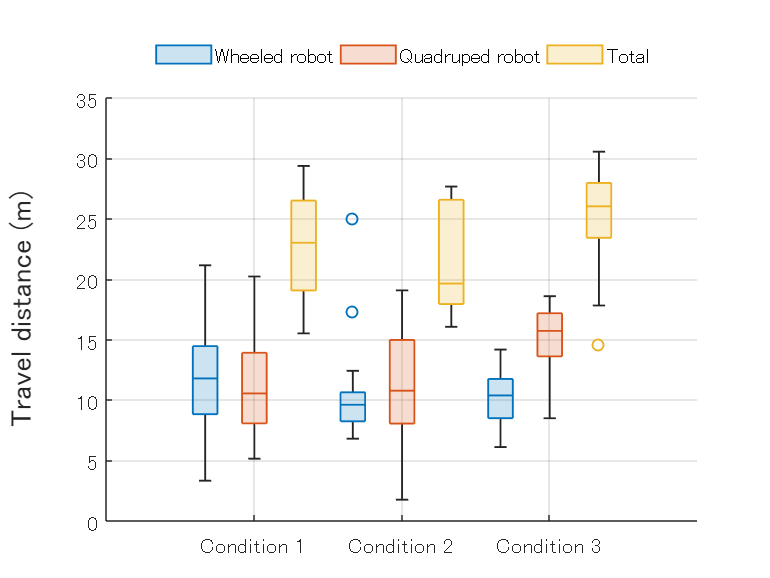




tbl = table( ...
    repmat({'Wheeled robot'}, [N, 1]), ...
    repmat({'Condition 1'}, [N, 1]), ...
    segway_mileage(:,1), ...
    VariableNames = ["robot", "condition", "mileage"]);

tbl = [
    tbl;
    table( ...
    repmat({'Wheeled robot'}, [N, 1]), ...
    repmat({'Condition 2'}, [N, 1]), ...
    segway_mileage(:,2), ...
    VariableNames = ["robot", "condition", "mileage"])
    ];
tbl = [
    tbl;
    table( ...
    repmat({'Wheeled robot'}, [N, 1]), ...
    repmat({'Condition 3'}, [N, 1]), ...
    segway_mileage(:,3), ...
    VariableNames = ["robot", "condition", "mileage"])
    ];

tbl = [
    tbl;
    table( ...
    repmat({'Quadruped robot'}, [N, 1]), ...
    repmat({'Condition 1'}, [N, 1]), ...
    a1_mileage(:,1), ...
    VariableNames = ["robot", "condition", "mileage"]);
    ];

tbl = [
    tbl;
    table( ...
    repmat({'Quadruped robot'}, [N, 1]), ...
    repmat({'Condition 2'}, [N, 1]), ...
    a1_mileage(:,2), ...
    VariableNames = ["robot", "condition", "mileage"])
    ];
tbl = [
    tbl;
    table( ...
    repmat({'Quadruped robot'}, [N, 1]), ...
    repmat({'Condition 3'}, [N, 1]), ...
    a1_mileage(:,3), ...
    VariableNames = ["robot", "condition", "mileage"])
    ];

tbl = [
    tbl;
    table( ...
    repmat({'Total'}, [N, 1]), ...
    repmat({'Condition 1'}, [N, 1]), ...
    total_mileage(:,1), ...
    VariableNames = ["robot", "condition", "mileage"]);
    ];

tbl = [
    tbl;
    table( ...
    repmat({'Total'}, [N, 1]), ...
    repmat({'Condition 2'}, [N, 1]), ...
    total_mileage(:,2), ...
    VariableNames = ["robot", "condition", "mileage"])
    ];
tbl = [
    tbl;
    table( ...
    repmat({'Total'}, [N, 1]), ...
    repmat({'Condition 3'}, [N, 1]), ...
    total_mileage(:,3), ...
    VariableNames = ["robot", "condition", "mileage"])
    ];

figure;

boxchart( ...
    categorical(tbl.condition, {'Condition 1', 'Condition 2', 'Condition 3'}), ...
    tbl.mileage, ...
    GroupByColor=categorical(tbl.robot, {'Wheeled robot', 'Quadruped robot', 'Total'}) ...
    );
ax = gca; ax.FontSize = 12;
ylabel({'Travel distance (m)', ''}, FontSize=16);
grid on;
legend(Location="northoutside", Orientation="horizontal", Box="off");

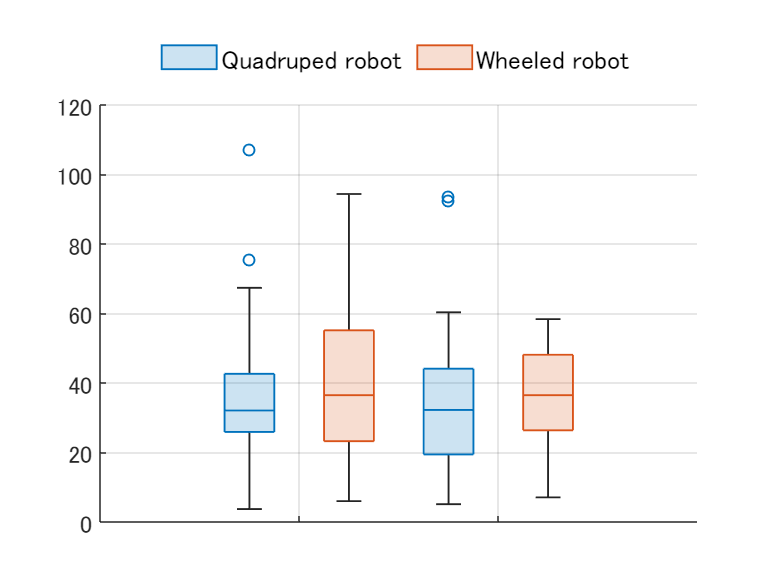


tbl = table( ...
    repmat({'Wheeled robot'}, [segway_interval(1,1,1), 1]), ...
    repmat({'Condition 1'}, [segway_interval(1,1,1), 1]), ...
    segway_interval(1,2:segway_interval(1,1,1)+1,1)', ...
    VariableNames = ["robot", "condition", "interval"]);


for k = 1:2
    if k == 1
        sidx = 2;
    else
        sidx = 1;
    end
    for idx = sidx:N
        tbl = [
            tbl;
            table( ...
            repmat({'Wheeled robot'}, [segway_interval(idx,1,k), 1]), ...
            repmat({sprintf('Condition %d', k)}, [segway_interval(idx,1,k), 1]), ...
            segway_interval(idx,2:segway_interval(idx,1,k)+1,k)', ...
            VariableNames = ["robot", "condition", "interval"]);
            ];
    end

    for idx = 1:N
        tbl = [
            tbl;
            table( ...
            repmat({'Quadruped robot'}, [a1_interval(idx,1,k), 1]), ...
            repmat({sprintf('Condition %d', k)}, [a1_interval(idx,1,k), 1]), ...
            a1_interval(idx,2:a1_interval(idx,1,k)+1,k)', ...
            VariableNames = ["robot", "condition", "interval"]);
            ];
    end
end

figure;

boxchart( ...
    categorical(tbl.condition, {'Condition 1', 'Condition 2'}), ...
    tbl.interval, ...
    GroupByColor=tbl.robot ...
    );
ax = gca; ax.FontSize = 13;
%ylabel({'Operation time', '', 'untill the robot will be replaced. (sec)', ''}, FontSize=15);
xticklabels([]);
grid on;
legend(Location="northoutside", Orientation="horizontal", Box="off", FontSize=14);
ylim([0,120]);

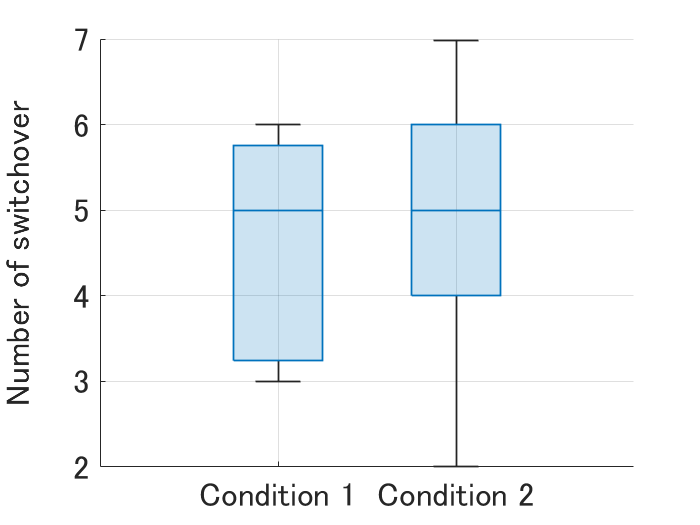


figure;

tbl = table( ...
    "Condition 1", ...
    segway_interval(1,1,1) + a1_interval(1,1,1), ...
    VariableNames = ["condition", "times"]);

for k = 1:2
    for idx = 2:N
        tbl = [
            tbl;
            table( ...
            sprintf("Condition %d", k), ...
            segway_interval(idx,1,k) + a1_interval(idx,1,k), ...
            VariableNames = ["condition", "times"]);
            ];
    end
end

figure;

boxchart( ...
    categorical(tbl.condition, {'Condition 1', 'Condition 2'}), ...
    tbl.times ...
    );
ax = gca; ax.FontSize = 20;
ylabel({'Number of switchover', ''}, FontSize=20);
grid on;
yticks(0:10);

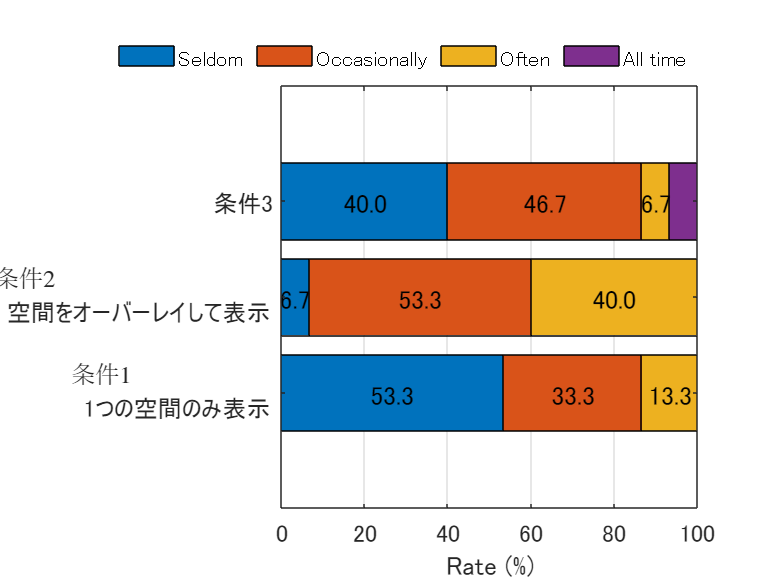


data = readcell("調査用紙 ver2（回答） - シート2.tsv", FileType="text");
data = cell2mat(data);

% 2つの空間に同時に存在しているように感じたことはありますか？
figure;
b = bar(data'/N*100, 'stacked', Horizontal='on');

for k = 1:length(b)-1
    ytips = b(k).XEndPoints;
    xtips = - b(k).YData/2 + b(k).YEndPoints;
    labels = [sprintf("%.1f", b(k).YData(1)), sprintf("%.1f", b(k).YData(2)), sprintf("%.1f", b(k).YData(3))];
    text(xtips,ytips,labels,'HorizontalAlignment','center',...
        'VerticalAlignment','middle', FontSize=14);
end

k = length(b);
xtips = b(k).XEndPoints(3);
ytips = - b(k).YData(3)/2 + b(k).YEndPoints(3);
labels = sprintf("%.1f", b(k).YData(3));
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','middle', FontSize=14);

xlabel('Rate (%)', FontSize=16);
% title("Feeling as if I existing two remote space in same time.", FontSize=18);
ax = gca; ax.FontSize = 13;
grid on; 
yticklabels({'条件1\newline 1つの空間のみ表示', '条件2\newline 空間をオーバーレイして表示', '条件3', 'hoge', 'hoge', 'hoge'});
%xtickangle(45);


legend('Seldom', 'Occasionally', 'Often', 'All time', Location="northoutside", Orientation="horizontal", Box="off");


standard_deviation1 = std(...
    [ ...
    ones([data(1,1), 1]);
    2*ones([data(2,1), 1]);
    3*ones([data(3,1), 1]);
    4*ones([data(4,1), 1]);
    ]...
    )

standard_deviation1 = 0.7368

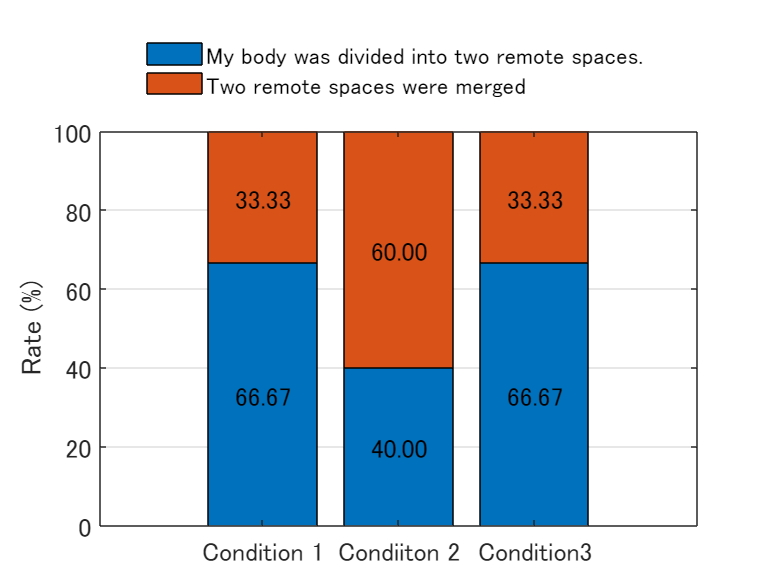


data = readcell("調査用紙 ver2（回答） - シート3.tsv", FileType="text");
data = cell2mat(data);
% 分身 or 融合
figure;
b = bar(data'/N*100, 'stacked');
for k = 1:length(b)
    xtips = b(k).XEndPoints;
    ytips = - b(k).YData/2 + b(k).YEndPoints;
    labels = [sprintf("%.2f", b(k).YData(1)), sprintf("%.2f", b(k).YData(2)), sprintf("%.2f", b(k).YData(3))];
    text(xtips,ytips,labels,'HorizontalAlignment','center',...
        'VerticalAlignment','middle', FontSize=14);
end
ylabel('Rate (%)', FontSize=18);
ax = gca; ax.FontSize = 14;
xticklabels({'Condition 1', 'Condiiton 2', 'Condition3'});
grid on;
legend('My body was divided into two remote spaces.', 'Two remote spaces were merged', Location="northoutside", Orientation="vertical", Box="off");


data = readcell("調査用紙 ver2（回答） - シート4.tsv", FileType="text");
data = cell2mat(data);



x = data(:,1) - data(:,2);

x_mean = mean(x);
mu = 0;
s2 = 1/(N - 1) * sum( (x - x_mean).^2 );

t = (x_mean - mu) / (s2/N)^0.5

t = -3.2404



alpha = 0.5

alpha = 0.5000